# Landscape

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
f(X) = \min_{Q} f(X,Q) = f\bigg(\frac{1}{k}\sum_j^k Y_jQ_j, Q\bigg) =f(\chi(Q),Q)
\\
\nabla f(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), \big(Y_j^\top(Y_jQ_j-X)\big)_j\bigg)
\\
\nabla^2 f(X,Q)[U,V] = \nabla f(U,V)$$


## Slices

seed=randi(100,1) %38

seed = 10

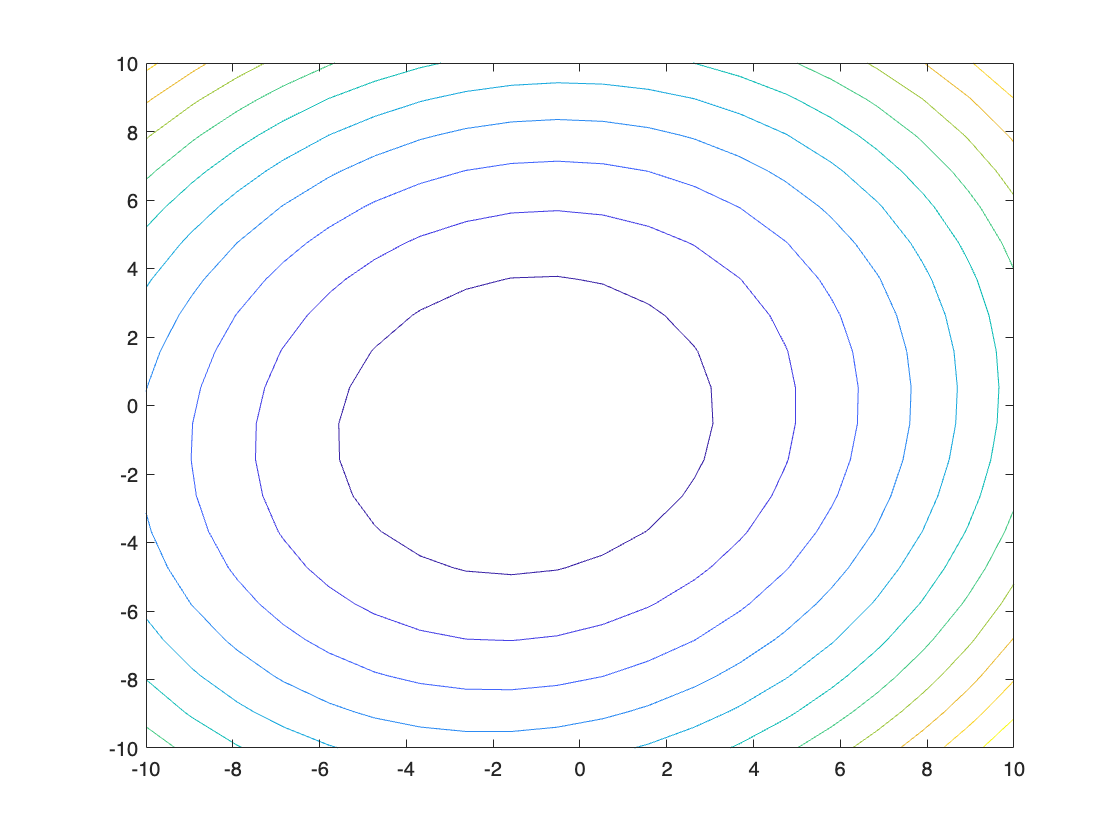

rng(seed)
n=32; % data dimension
r=2; % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B
k=100; % number of matrices
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

t = linspace(-10,10,20);
costs = surfprofile(prob,[],[],[],t,t);
contour(t, t, costs.')

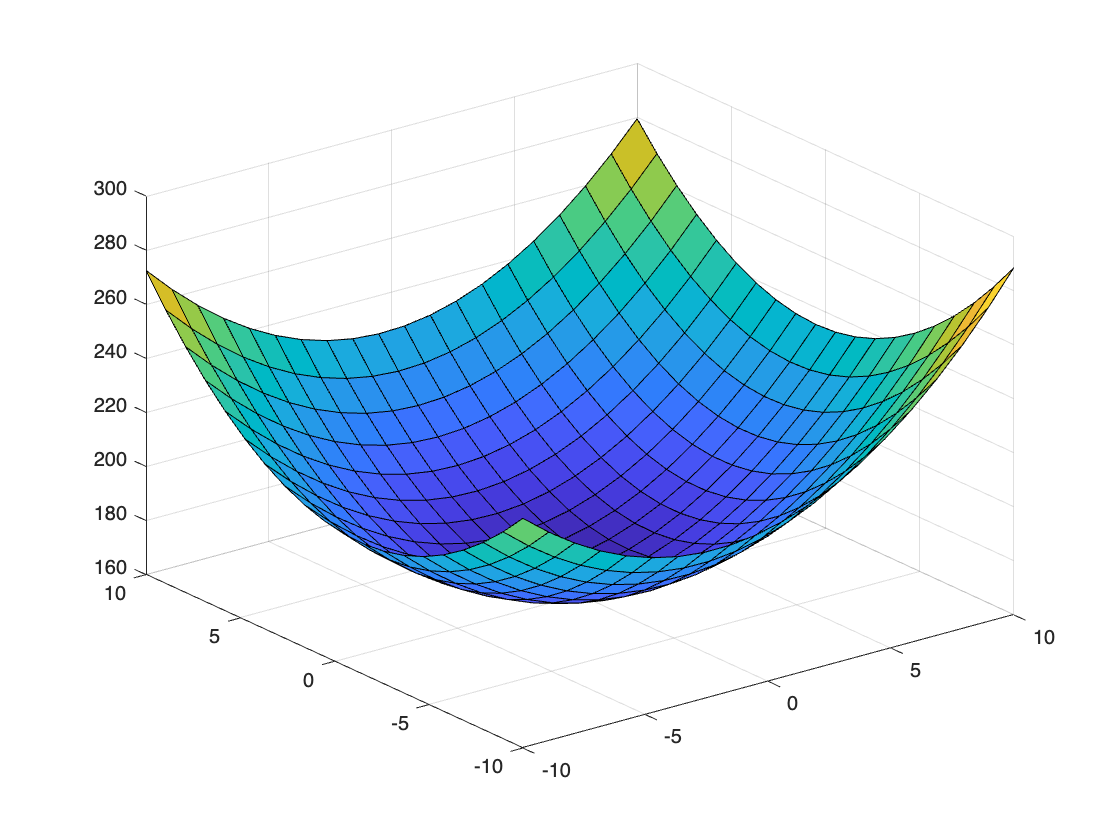

surf(t, t, costs.')

## Dependance to the initialization

clear
n=32; % data dimension
rr=round(logspace(0,log10(n),7)); % size of factorization Y of data A (chose <8 if n=32)
pp=rr; % size of factorization X of barycenter B
k=100; % number of matrices
Nrepeat=10;

mybar = waitbar(0,"Initialization");
Brelative_std = NaN(length(rr));
niter = NaN(length(rr));
options.verbosity=0;

for jr=1:length(rr)
    r=rr(jr);
    for jp=jr:length(pp)
        p=pp(jp);

        A = data(n,k,r);
        prob = nonconvex_problem(A,r,p);
        X = zeros(n,p,Nrepeat);
        niter(jr,jp)=0;

        for j=1:Nrepeat
            waitbar((jr+(jp+j/Nrepeat)/length(pp))/length(rr), mybar,...
                sprintf("(r,p)/n=(%d,%d)/%d \n iteration %d/%d",r,p,n,j,Nrepeat))
            [x,~,info] = trustregions(prob,[],options);
            X(:,:,j) = x.X;
            niter(jr,jp) = niter(jr,jp) + info(end).iter;
        end
        
        niter(jr,jp) = niter(jr,jp) / Nrepeat;
        BB = pagemtimes(X, multitransp(X));
        Bmean = sum(BB,3)/Nrepeat;
        Bstd = norm(Bmean-BB,"fro")/(Nrepeat-1);
        Brelative_std(jr,jp) = Bstd/norm(Bmean,"fro");
    end
end
close(mybar)
%save("data/consitency_rp.mat","Brelative_std","niter")

load("data/consitency_rp.mat")
heatmap(pp,rr,Brelative_std)

Unrecognized function or variable
'pp'.

title(sprintf("Relative STD \n %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
%exportgraphics(gcf,"graphics/landscape_relative_std.pdf")
heatmap(pp,rr,niter)
title(sprintf("Number of iterations \n %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
%exportgraphics(gcf,"graphics/landscape_iterations.pdf")

## Convergence to global minimum

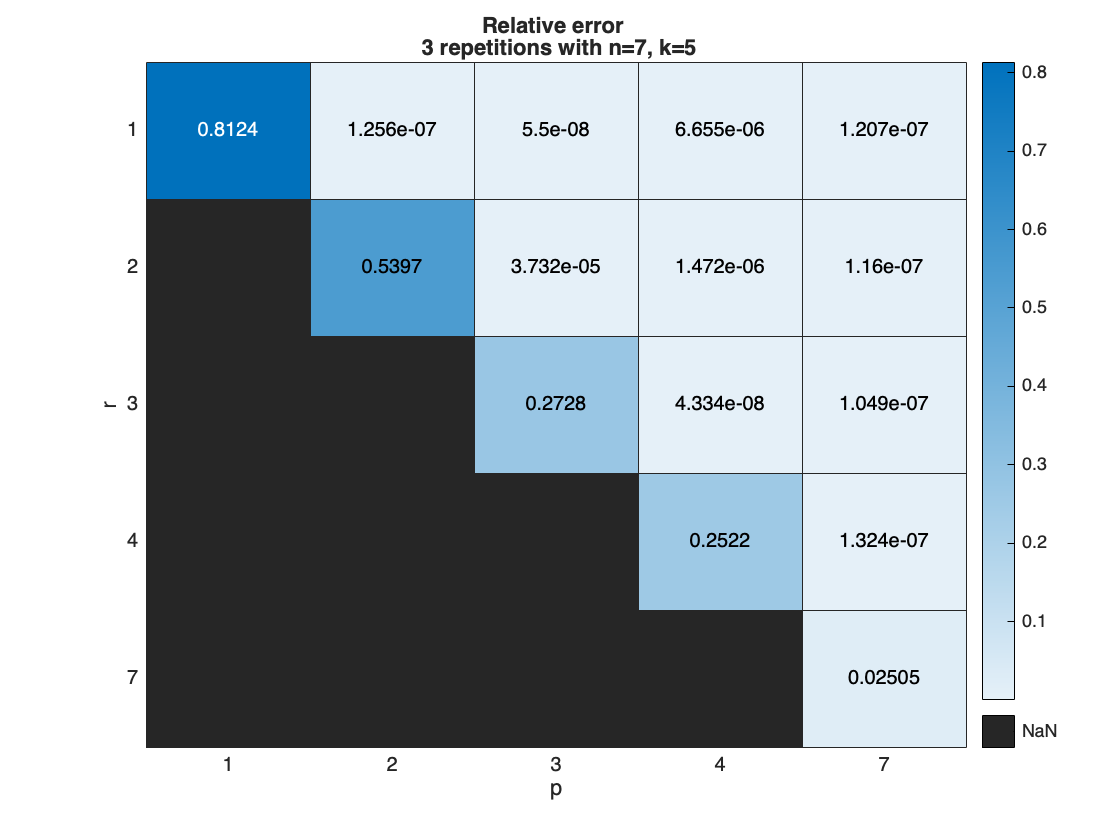

clear
n=7; % data dimension
rr=round(logspace(0,log10(n),5)); % size of factorization Y of data A (chose <8 if n=32)
pp=rr; % size of factorization X of barycenter B
k=5; % number of matrices
Nrepeat=3;

mybar = waitbar(0,"Initialization");
Brelative_err = NaN(length(rr));
niter = NaN(length(rr));
options.verbosity=0;

for jr=1:length(rr)
    r=rr(jr);
    for jp=jr:length(pp)
        p=pp(jp);

        A = data(n,k,r);
        prob = nonconvex_problem(A,r,p);
        X = zeros(n,p,Nrepeat);
        niter(jr,jp)=0;

        for j=1:Nrepeat
            waitbar((jr+(jp+j/Nrepeat)/length(pp))/length(rr), mybar,...
                sprintf("(r,p)/n=(%d,%d)/%d \n iteration %d/%d",r,p,n,j,Nrepeat))
            [x,~,info] = trustregions(prob,[],options);
            X(:,:,j) = x.X;
            niter(jr,jp) = niter(jr,jp) + info(end).iter;
        end
        
        niter(jr,jp) = niter(jr,jp) / Nrepeat;
        BB = pagemtimes(X, multitransp(X));
        Btrue = cvx_solve(prob.A);
        Berr = mean(pagenorm(Btrue-BB,"fro")); % use BW distance instead of Frobenius norm?
        Brelative_err(jr,jp) = Berr/norm(Btrue,"fro");
    end
end
close(mybar)
save("data/reliability_rp.mat","Brelative_err","niter")

heatmap(pp,rr,Brelative_err)
title(sprintf("Relative error \n %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
exportgraphics(gcf,"graphics/landscape_relative_err.pdf")

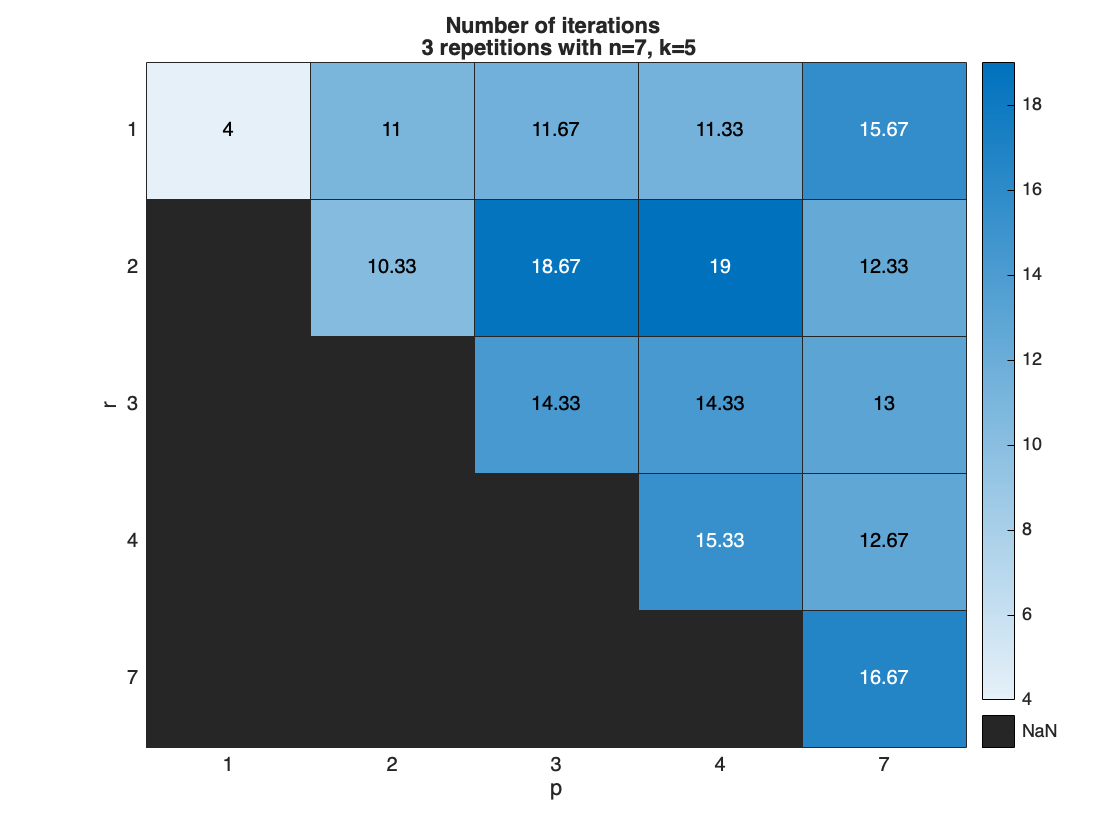

heatmap(pp,rr,niter)
title(sprintf("Number of iterations \n %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")

exportgraphics(gcf,"graphics/landscape_iterations2.pdf")

## Rank of solutions

clear
n=5; % data dimension
kk=2:2:10; % number of matrices
rr=1:n;
Nrepeat=5;
eigenvalues= zeros(length(kk),length(rr),n,Nrepeat);
for jk=1:length(kk)
    k=kk(jk);
    for jr=1:length(rr)
        r=rr(jr);
        for j=1:Nrepeat
            A = data(n,k,r);
            [B,Bcost,info] = cvx_solve(A);
            eigenvalues(jk,jr,:,j)=abs(eig(B));
        end
    end
end

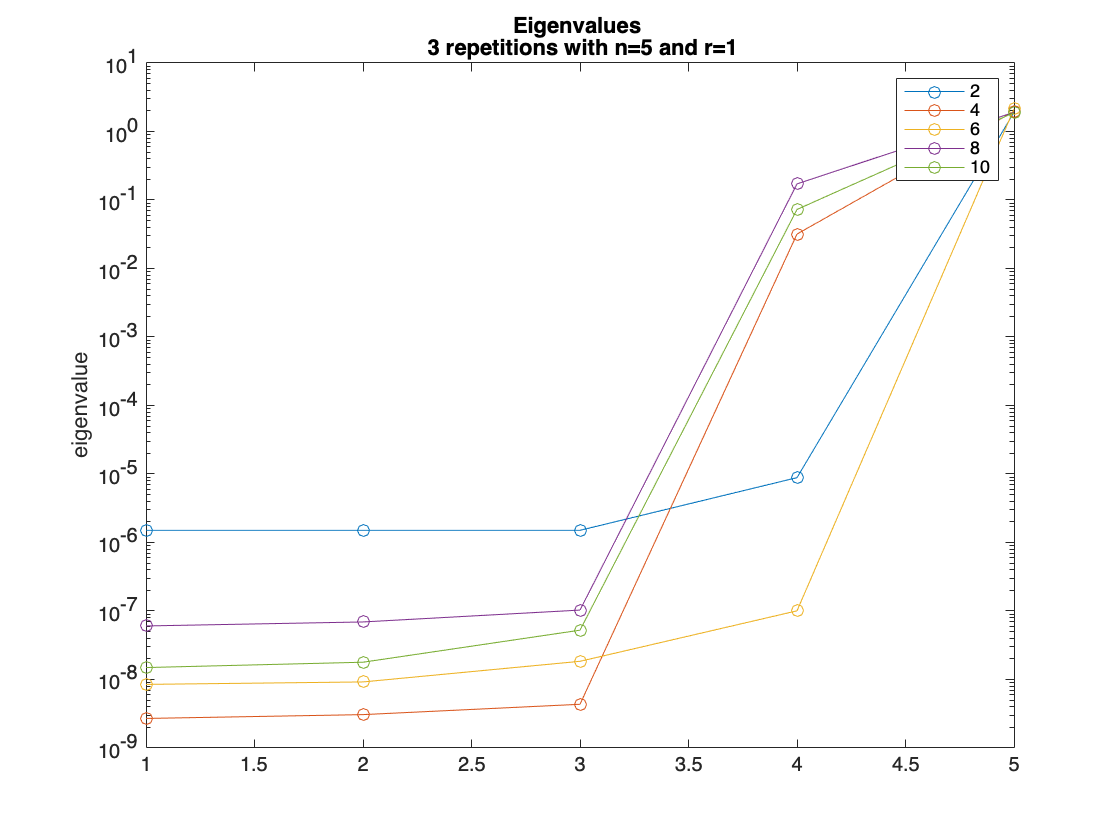

for jr=1:length(rr)
    eig_mean = mean(eigenvalues(:,jr,:,:),4);
    semilogy(squeeze(eig_mean)',"o-")
    title(sprintf("Eigenvalues of true Barycenter \n %d repetitions with n=%d and r=%d",Nrepeat,n,rr(jr)))
    ylabel("eigenvalue")
    legend(string(kk))
    exportgraphics(gcf,sprintf("graphics/rank_r%d.pdf",rr(jr)))
end